# **Estimation of Directions and Frequencies**

### Signal model

- More samples means higher singular values (mainly the two first/highest elements). The increase is approximately a 40% increase when doubling the sampling amount. The lower three singular values change slightly, and become more flattened for higher signals (relative smaller difference w.r.t. eachother).

- Note also that we get 2 large singular values and rest at noise level, which makes sense since we generate the data for 2 sources and we expect rank(X) = 2.

clear; clc; close all;
% dataset = load("joint_diag.mat");

function [X,A,S] = gendata(M,N,Delta,theta,f,SNR)
% Function to generate data based on the model X = A S + W (for ULA)
%
% Inputs:
%   M      - number of antennas
%   N      - number of samples
%   Delta  - antenna spacing (in wavelengths, typically 0.5)
%   theta  - [1 x d] source directions in degrees
%   f      - [1 x d] normalized frequencies (0 <= fi < 1)
%   SNR    - [1 x d] SNR per source (linear scale, not dB)
%
% Outputs:
%   X - M x N received signal matrix
%   A - M x d steering matrix
%   S - d x N source signal matrix

    L = length(theta);          % number of sources
    theta_rad = deg2rad(theta); % convert degrees to radians

    % --- Steering matrix A: M x L ---
    % ULA steering vector for source l:
    % a_l = [1, exp(j*2pi*Delta*sin(θ_l)), ..., exp(j*2pi*(M-1)*Delta*sin(θ_l))]^T
    A = zeros(M, L);
    for l = 1:L
        for m = 1:M
            A(m,l) = exp(1j * 2*pi * (m-1) * Delta * sin(theta_rad(l)));
        end
    end

    % --- Source matrix S: L x N ---
    % i-th source: s_{i,k} = exp(j*2*pi*f_i*k)
    S = zeros(L, N);
    for l = 1:L
        for n = 1:N
            S(l,n) = exp(1j * 2*pi * f(l) * n);
        end
    end

    % --- Noise: scale per source to achieve desired SNR ---
    % SNR_l = signal_power_l / noise_power
    % signal power of source l at any antenna = 1 (unit amplitude sinusoid)
    % so noise std = 1/sqrt(SNR_l) per source contribution
    % We generate a single M x N complex white Gaussian noise matrix:
    % noise power = sigma^2 = mean over sources of (1/SNR_l)
    sigma2 = mean(1 ./ SNR);                         % average noise variance
    W = sqrt(sigma2/2) * (randn(M,N) + 1j*randn(M,N));

    % --- Received signal matrix ---
    X = A * S + W;
end

% Define variables (ground truth) and generate data (measurements)

M = 5

N = 20

theta =    -20
    30


f =     0.1000
    0.3000


SNR = 20

Delta = 0.5000

M = 5, N = 20, theta = [-20, 30]' , f = [0.1, 0.3]', SNR = 20, Delta = .5
[X,A,S] = gendata(M,N,Delta,theta,f,SNR);

% Check singular values
[U_x,S_x,V_x] = svd(X);

ans =    10.2336
    9.8283
    1.1714
    0.9119
    0.8215


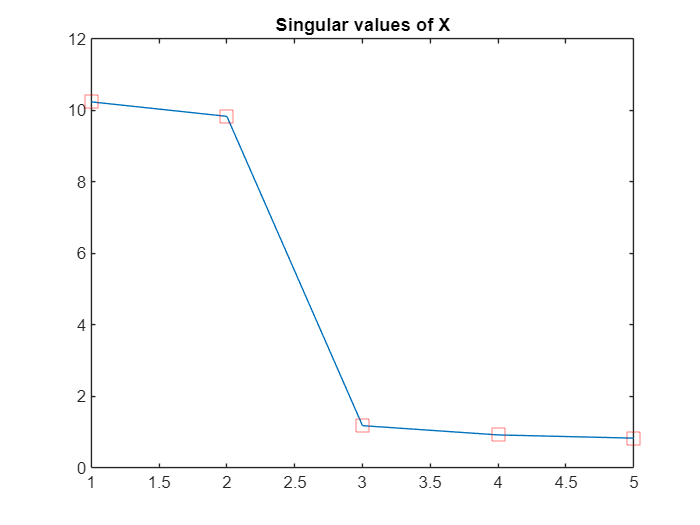

diag(S_x) % M diagonal elements
plot(linspace(1,M,M),diag(S_x), '-s', 'MarkerSize',10, 'MarkerEdgeColor', 'r')

title("Singular values of X")

### Estimation of directions

function theta = esprit(X,d)
    % ESPRIT algorithm for DOA estimation
    % X: M x N data matrix (M sensors, N snapshots)
    % d: number of sources
    % Delta: inter-element spacing in wavelengths (typically 0.5)

% X is the data matrix and d is the number of sources
% We know X = A*B*S, Phi = diag(phi) = diag(e^(j*2*pi*Delta*sin(theta(k)))
% Our goal is to recover the theta matrix and Y = AthetaBS while X = ABS

    % Augment the system as Z = [X,Y]' --> take Y as shifted version of X
    % Build the shift-invariant matrix pair
    Z = [X(1:end-1, :);X(2:end, :)]; % = [A; A*Phi]*BS --> Z is given measurements --> [2(M-1) x N]

    % SVD: Z = USV' (U ~ [2M x d] --> span(U) ~ Z, A (rank(z) = d)
    [U_z, S_z, V_z] = svd(Z); % --> can be split into Ux and Uy part
    M = size(U_z,1)/2; % --> could also replace '1:M' with '1:end/2', note that M = M-1 here
    U_x = U_z(1:M, 1:d); % Truncate SVD to (left) d most dominant (singular) vectors since rank=d (signal subspace dim)
    U_y = U_z(M+1:end, 1:d);

    % We take the eigendecomposition of U'xUy = inv(T)thetaT
    [T,Phi] = eig(pinv(U_x)*U_y); % Note that inv(T) may not exist and T is not necessarily square

    %% Extract DOAs from eigenvalues
    % Phi contains the angles phi_k and theta_k, assume Delta is given
    Delta = .5; % Assume Delta=1/2 for now (typically), could also give as input
    phi = diag(Phi); % diag(A) return diagonal elements of A as a columns vector
    theta = real(asin(log(phi) / (1j*2*pi*Delta))) * 180/pi; % extract the angular delays 'theta' from Phi --> conv to deg
end

function d_hat = sigVal_rankTest(S, a)
% Apply relative threshold (a) singular value (s) test to estimate the rank (d) of a matrix Z = USV' 
    s_diag = diag(S);
    s_diag = s_diag(s_diag > a * max(s_diag));
    d_hat = size(s_diag,1)
end

a = 0.5;

d_hat = 2

d_hat = sigVal_rankTest(S_x, a);

theta_est =    29.9373
  -20.0898


theta_est = esprit(X,d_hat) % check what to use for 'd'

SNR_th = 5.3500e-04

SNR_th = snr(theta,theta_est)

### Estimation of frequencies

- 1) In  the model X = AS, we know that S should have the same amount of rows as A has columns ( row(X) = row(S) ), and that we require A to be full rank (=d) for a unique solution S = pinv(A)X to exist, which is generally satisfied in the noiseless case.

function f = espritfreq(X,d)
% ESPRIT subspace estimation for shift invariant model: x(t) = sum_k a_k * exp(j*2*pi*f_k*t)
% 
% Inputs:
% - x: 1 x N signal vector
% - d: number of complex exponentials
% 
% Outputs:
% - f: frequency to be estimated

    Z = [X(:, 1:end-1) ; X(:, 2:end)];   % [2M x N-1], temporal shift
    [U_z, ~, ~] = svd(Z);
    M = size(U_z,1)/2;
    U_x = U_z(1:M, 1:d);
    U_y = U_z(M+1:end, 1:d);

    [~,Phi] = eig(pinv(U_x)*U_y); % expanding Ux'Uy = V'DV, Phi = D
    phi = diag(Phi);

    % Convert phase to frequency (normalized frequency since no notion of fs)
    f = real(angle(phi) / (2*pi));
end


f_est =     0.3012
    0.0980


f_est = espritfreq(X,d_hat)

SNR_f = -0.0136

SNR_f = snr(f,f_est)

### Joint estimation of directions and frequencies

- Solving jointly gives better performance than solving both problems seperately, since if there are multiple elements on the diagonal of one Phi matrix equal then this gives some degrees of freedom in the eigenvector-like (transformation) matrix. The probability of these elements being equal in both Phi matrices is small and therefore it's more likely that we get a non-diagonal matrix if we use the transformation matrix T from solving decomposition one to solve the other decomposition. 

- Use khatri-rao for joint diagonalization: USV' --> with stacked system [X;Y;Z] = (kr{F,A}) S, such that U_top[1.M-1] = kr{F'',A} T , U_bottomkr{F'',A} for both time(phi) and space(theta) estimations. Since we already pre-emptively defined the kr{F,A} matrix, the transformation matrix is not arbitrary anymore and we get a unique solution (roational ambiguity is eliminated by the Khatri-Rao structure). ( kr{.} = Khatri-Rao Product = column-wise kronecker product )

- Joint estimation is achieved through a joint eigenbasis: T' D1 T & T' D2 T, also called simultaneous diagonalization. In order for this to exist, we require the matrices D1 & D2 to commute (i.e. D1 D2 = D2 D1). One important notion here is that the ordering for any eigenbasis is arbitrary, but in the joint case the ordering between D1 and D2 are the same since they share the same eigenvectors T.

- Advantage of ESPRIT is that its efficient for higher dimensional searches. Additionally, the signal vs. noise splitting can be effectively done in subspace domain. One parameter that should be taken into account however, is the rank 'd', serving as a model parameter that is to be extracted from the data.

- Advantage of joint diag: { keeps ordering of both estimates equivalent (due to common eigenstructure constraints), incorporates more data, and improved robustness to noise}. However, degenerate eigenvalues can still cause issues, since in practice the matrices only approximately commute.

function [theta,f] = joint(X,d,m)
    % Define smoothing parameters, averaging over blocks in time/space
    [M, N] = size(X);   % number of overlapping blocks --> instead use as function parameter 'm'
    K = N - m + 1;      % (time-row) block length (m is number of blocks)
    L = 2*(M-1);        % (space-column) block length (assuming 2x spatial smoothing (Z = [X; Y])
    
    % First apply the spatial 'smoothing' (with factor 2) i.e. Z = [X;Y]
    Z = [X(1:end-1, :);X(2:end, :)]; % [2(M-1) x N]

    % --- Build smoothed Z by stacking L blocks (1-shifted versions) ---
    Z_smooth = zeros(m*L, K); % [ m2(M-1) x N-m+1 ]
    for i = 1:m
        % Extract block i
        Z_i = Z(:, i:K+i-1); % take 'm' 1-shifted versions of length 'N-m+1'
        Z_smooth((i-1)*L+1 : i*L, :) = Z_i; % Vertically stack (=vec(.)) the shifted version to get SI structure
    end

    % Compute SVD
    [U,~,~] = svd(Z_smooth);
    U = U(:, 1:d);
    
    % Partition the spatial smoothing part
    Ux = []; Uy = [];
    for i = 1:m % Loop over the block to partition U, this is more efficient that doing multiple SVD's
        Ui = U((i-1)*L+1 : i*L, :); % partition into 'm' segments of length '2(M-1)' (temporal splitting)
        % Uix = Ui(1:M-1, :); Uiy = Ui(2:M, :); % partition into '2' segments of length 'M-1' (spatial splitting)
        % Extract the 1:d part since in rank (in space) = d
         % we know span(col(U))=span(col(Z)), then Ux = [u1x;...;uLx]
        Ux = [Ux; Ui(1:M-1, :)]; Uy = [Uy; Ui(M:end, :)]; % Take 1st 'M-1' for x and 2nd 'M-1' for y
    end
    
    % Partition the temporal smoothing part
    Ut_top = []; Ut_bot = [];
    for i = 1:m-1
        Ut_top = [Ut_top; U((i-1)*L+1 : i*L,     1:d)];
        Ut_bot = [Ut_bot; U(i*L+1     : (i+1)*L, 1:d)];
    end
    Ut_top = U(1:m*(M-1), :); Ut_bot = U(m*(M-1)+1:m*2*(M-1), :);
    
    % Define rotation operators for joint_diag --> Need A = space (x) time
    Psi_space = pinv(Ux) * Uy;   % spatial eigenvalues → sin(theta_k)
    Psi_time = pinv(Ut_top) * Ut_bot;   % temporal eigenvalues → f_k / fs
    
    % Joint diagonalization
    [ ~ , D ] =  joint_diag([Psi_space, Psi_time], 1e-8); % approx. inv(T)DT
    
    % Extract paired eigenvalues
    phi_space = diag(D(:, 1:d));   % first 'd' eigvals → sin(theta_k)
    phi_time  = diag(D(:,d+1:2*d));   % second 'd' eigvals → f_k / fs

    % Recover theta, f
    Delta = 0.5;
    theta = real(asin(log(phi_space) / (1j*2*pi*Delta))) * 180/pi;
    f = angle(phi_time) / (2*pi);

theta_est_joint =    29.7815
  -20.0129


f_est_joint =     0.3017
    0.0976


end

SNR_joint = 0.0421


% Run function to check correctness
m = 2;
[theta_est_joint,f_est_joint] = joint(X,d_hat,m) % Should be same as ground truth (from gendata): theta = [-20, 30]' , f = [0.1, 0.3]'
SNR_joint = snr([theta, f], [theta_est_joint, f_est_joint])

### Comparison

- [*Noiseless case*]: The frequency ESPRIT gives the best supression (SNR =~ -0.003). This is likely due to the effectiveness of the time smoothing as compared to the spatial smoothing. A possibility is that the time axis has length N >> M (spatial axis), and thus yields larger smoothing block lengths, leading to effective noise averaging whilsts still ensuring a reliable estimate.

- [*Noise SNR sweep (m=2)*]: The joint estimation gives the best estimations, especially noticable for the lower SNR's. We see that for the lower SNR ranges, the joint estimates converge way faster towards the true estimate, whilst the seperate one's are slower to converge. This indicates that the Joint-ESPRIT has better overall noise resilience (apart from the noiseless case which could be due to higher complexity nature and ambiguities of joint estimation). This is likely because of the combined spatial and temporal smoothing, on top of that this function can use any smoothing split 'm' instead of fixed 2 (although this test used m=2).

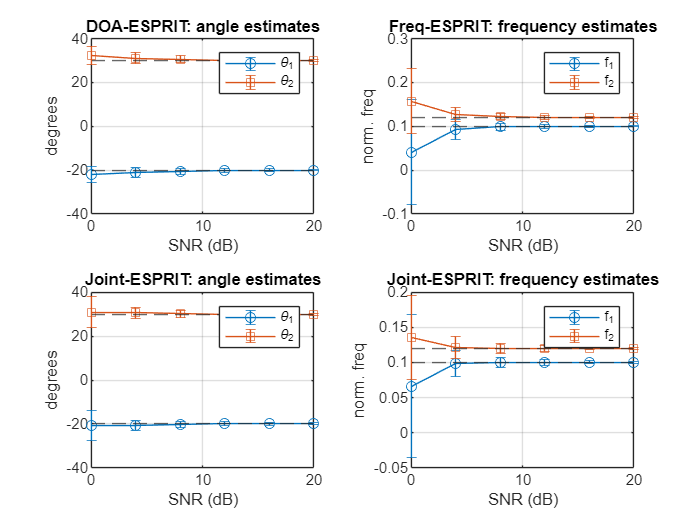

SNR_dB  = 0:4:20;
n_runs  = 1000;
d       = 2; M = 3; N = 20; Delta = 0.5;
theta   = [-20, 30];
f       = [0.1, 0.12];

% Preallocate: [n_SNR x n_runs x d]
theta_est_dir   = zeros(length(SNR_dB), n_runs, d);
f_est_freq      = zeros(length(SNR_dB), n_runs, d);
theta_est_joint = zeros(length(SNR_dB), n_runs, d);
f_est_joint     = zeros(length(SNR_dB), n_runs, d);

for si = 1:length(SNR_dB)
    SNR_lin = 10^(SNR_dB(si)/10) * ones(1,d);
    for r = 1:n_runs
        X = gendata(M, N, Delta, theta, f, SNR_lin);
        
        theta_est_dir(si, r, :)   = sort(esprit(X, d));
        f_est_freq(si, r, :)      = sort(espritfreq(X, d));
        [th_j, f_j]               = joint(X, d, m);
        theta_est_joint(si, r, :) = sort(th_j);
        f_est_joint(si, r, :)     = sort(f_j);
    end
end

% Compute mean and std over runs (dim 2)
theta_mean_dir    = squeeze(mean(theta_est_dir,   2));   % [n_SNR x d]
theta_std_dir     = squeeze(std(theta_est_dir,    0, 2));
f_mean_freq       = squeeze(mean(f_est_freq,      2));
f_std_freq        = squeeze(std(f_est_freq,       0, 2));
theta_mean_joint  = squeeze(mean(theta_est_joint, 2));
theta_std_joint   = squeeze(std(theta_est_joint,  0, 2));
f_mean_joint      = squeeze(mean(f_est_joint,     2));
f_std_joint       = squeeze(std(f_est_joint,      0, 2));

figure;
tiledlayout(2, 2);

% --- Angle estimates ---
nexttile;
errorbar(SNR_dB, theta_mean_dir(:,1),  theta_std_dir(:,1),  '-o'); hold on;
errorbar(SNR_dB, theta_mean_dir(:,2),  theta_std_dir(:,2),  '-s');
yline(theta(1), '--'); yline(theta(2), '--');
xlabel('SNR (dB)'); ylabel('degrees');
title('DOA-ESPRIT: angle estimates');
legend('\theta_1', '\theta_2'); grid on;

nexttile;
errorbar(SNR_dB, f_mean_freq(:,1),  f_std_freq(:,1),  '-o'); hold on;
errorbar(SNR_dB, f_mean_freq(:,2),  f_std_freq(:,2),  '-s');
yline(f(1), '--'); yline(f(2), '--');
xlabel('SNR (dB)'); ylabel('norm. freq');
title('Freq-ESPRIT: frequency estimates');
legend('f_1', 'f_2'); grid on;

nexttile;
errorbar(SNR_dB, theta_mean_joint(:,1), theta_std_joint(:,1), '-o'); hold on;
errorbar(SNR_dB, theta_mean_joint(:,2), theta_std_joint(:,2), '-s');
yline(theta(1), '--'); yline(theta(2), '--');
xlabel('SNR (dB)'); ylabel('degrees');
title('Joint-ESPRIT: angle estimates');
legend('\theta_1', '\theta_2'); grid on;

nexttile;

errorbar(SNR_dB, f_mean_joint(:,1), f_std_joint(:,1), '-o'); hold on;
errorbar(SNR_dB, f_mean_joint(:,2), f_std_joint(:,2), '-s');
yline(f(1), '--'); yline(f(2), '--');
xlabel('SNR (dB)'); ylabel('norm. freq');
title('Joint-ESPRIT: frequency estimates');
legend('f_1', 'f_2'); grid on;

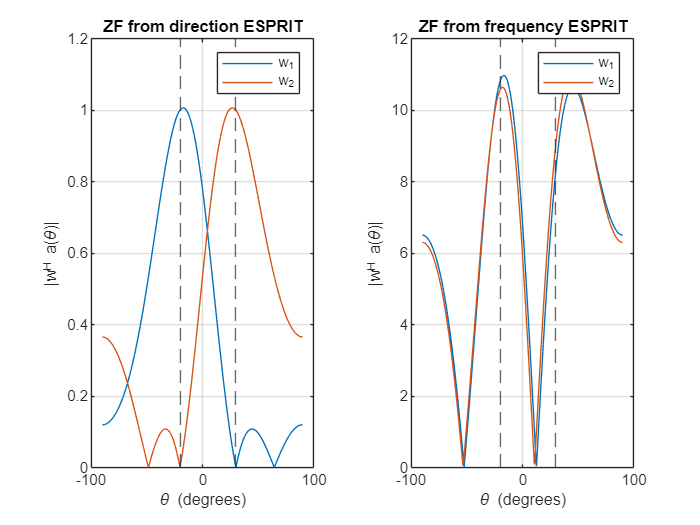

% --- Build data and estimates ---
SNR_lin = 10^(10/10); % =10
X = gendata(M, N, Delta, theta, f, SNR_lin);
R = (X * X') / N;

% --- Estimate directions and frequencies ---
theta_est = sort(esprit(X, d));     % [1 x d] in degrees
f_est     = sort(espritfreq(X, d)); % [1 x d] normalized frequencies

% --- Build steering matrix from direction estimates ---
A_d = zeros(M, d);
for k = 1:d
    for m = 1:M
        A_d(m,k) = exp(1j * 2*pi * (m-1) * Delta * sin(deg2rad(theta_est(k))));
    end
end

% --- Build steering matrix from frequency estimates ---
% Invert the ESPRIT phase relationship: phi = exp(j*2pi*Delta*sin(theta))
% so sin(theta) = angle(phi)/(2pi*Delta) --> theta = asin(angle(phi)/(2pi*Delta))
% Then build A_f the same way using theta derived from f_est
% phi_f = exp(j*2pi*f) from temporal ESPRIT, spatial phase = 2pi*Delta*sin(theta)
% For fair comparison just build A from f-derived angles:
theta_from_f = real(asin(f_est / Delta)) * 180/pi;  % recover angle from freq estimate
A_f = zeros(M, d);
for k = 1:d
    for m = 1:M
        A_f(m,k) = exp(1j * 2*pi * (m-1) * Delta * sin(deg2rad(theta_from_f(k))));
    end
end

% --- Zero-forcing beamformers: W = pinv(A) = inv(A'A)*A' ---
% Each column of W is one beamformer vector [M x 1]
W_d = A_d * inv(A_d' * A_d);   % [M x d], ZF from direction ESPRIT
W_f = A_f * inv(A_f' * A_f);   % [M x d], ZF from frequency ESPRIT

% --- Correctness check (no noise): W'*X should recover S = inv(A'A)*A'*AS = S ---
S_est_d = W_d' * X;   % [d x N]
S_est_f  = W_f' * X;

% --- Spatial response: y(theta) = |w^H * a(theta)| ---
theta_scan = linspace(-90, 90, 500);
response_d = zeros(d, length(theta_scan));
response_f = zeros(d, length(theta_scan));

for ti = 1:length(theta_scan)
    a_scan = zeros(M, 1);
    for m = 1:M
        a_scan(m) = exp(1j * 2*pi * (m-1) * Delta * sin(deg2rad(theta_scan(ti))));
    end
    for k = 1:d
        response_d(k,ti) = abs(W_d(:,k)' * a_scan);
        response_f(k,ti) = abs(W_f(:,k)' * a_scan);
    end
end

% --- Plot spatial responses ---
figure; tiledlayout(1,2);

nexttile;
plot(theta_scan, response_d(1,:)); hold on;
plot(theta_scan, response_d(2,:));
xline(theta(1),'--'); xline(theta(2),'--');
xlabel('\theta (degrees)'); ylabel('|w^H a(\theta)|');
title('ZF from direction ESPRIT');
legend('w_1','w_2'); grid on;

nexttile;

plot(theta_scan, response_f(1,:)); hold on;
plot(theta_scan, response_f(2,:));
xline(theta(1),'--'); xline(theta(2),'--');
xlabel('\theta (degrees)'); ylabel('|w^H a(\theta)|');
title('ZF from frequency ESPRIT');
legend('w_1','w_2'); grid on;

# **Channel Equalization**

### Signal Model

- Initially, for no noise (sigma=0), the rank should be full rank (=min{N,M} for X ~ [N x M]) and scale as $\frac{1}{P}$, since upsampling just adds linearly dependent rows. Therefore we expect (still for sigma=0) that: $\mathrm{rank}\left(X\right)=\min \left\lbrace \frac{\mathrm{LP},}{P},N-L+1\right\rbrace =L=\mathrm{rank}\left(H\right)$ (=2 for L=2) , generally since (N >> L, P). 

- If we double P we get a longer matrix, but including more padded zeros, thus the rank itself should not change, we would only be adding more linearly dependent rows. By the expression derived above, we expect a doubling of P to result in the rank of X to be the same (=2) in case N-L+1 > 2P.

function h = make_h(P)
% Function that builds the impulse response for QPSK for general P
% h has size [P x 1]
    t = (0:P-1)/P;  % sample points in [0,1)
    h = zeros(P,1);
    h(t < 0.25)             = 1;
    h(t >= 0.25 & t < 0.5)  = -1;
    h(t >= 0.5 & t < 0.75)  = 1;
    h(t >= 0.75)            = -1;
end

function s_up = upsampler(s, P, method)
    N = length(s);
    s_up = zeros(N*P, 1);
    
    switch method
        case 'zero_pad' % Upsample 's' by inserting 'P-1' zeros between symbols
            s_up(1:P:end) = s;
    
        case 'repeat' % Upsample by inserting 'P-1' copies of most recent symbol
            for n = 1:N
                idx = (n-1)*P + (1:P);
                s_up(idx) = s(n);
            end
    
        case 'linear_interpolate' % Upsample by linearly interpolating the value between symbols
            s_up(1:P:end) = s;
            for n = 1:N-1
                for p = 1:P-1
                    frac = p/P;
                    s_up((n-1)*P + 1 + p) = (1-frac)*s(n) + frac*s(n+1);
                end
            end
            % last block: hold last value (no next sample to interpolate to)
            for p = 1:P-1
                s_up((N-1)*P + 1 + p) = s(N);
            end
    
        otherwise
            error('Unknown method: %s', method);
    end
end

function [x, H] = gendata_conv(s,P,N,sigma)
% Generate data function (1/P oversampled) for single user (M=1) --> convolutional model s(x) * h(x)
%
% Inputs:
% - s: QPSK (4 symbol classes) modulated input signal [N x 1]
% - P: oversampling factor (one period = P samples)
% - N: number of symbols
% - sigma: noise std
%
% Outputs:
% - x: oversampled received signal vector [NP x 1]

    % --- Oversampled (padded) signal: P x 1 ---
    s_oversampled = upsampler(s, P, 'zero_pad');      
    
    % --- Impulse resonse h: P x 1 ---
    h = make_h(P);                      % Channel impulse response, sampled at rate '1/P', [P x 1]
    hs_conv = conv(h, s_oversampled);   % Convolve, [P + NP - 1 x 1] = [(N+1)P - 1 x 1]
    hs_trunc = hs_conv(1:N*P);          % Truncate to length 'NP', [NP x 1]

    % --- Received signal matrix ---
    w = sigma * (randn(N*P,1) + 1j*randn(N*P,1)) / sqrt(2);     % Complex White Gaussian Noise
    x = hs_trunc + w;                                           % [ NP x 1 ]
    
end

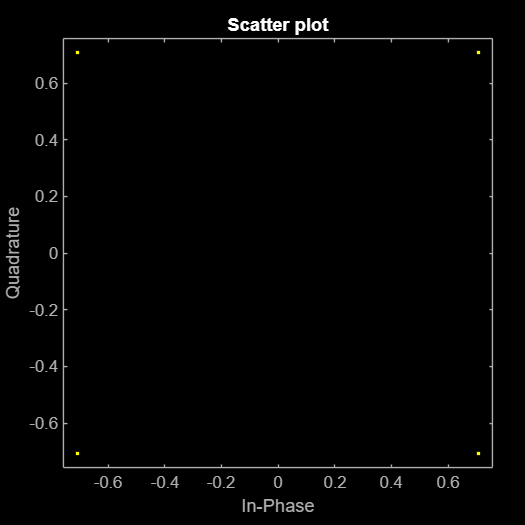

P=4; N=500; sigma=0; % use sigma=0 for rank analysis (full rank/P)

function s_tx = PSK_gen(C,N, sigma)
% Phase Shift Keying data generator
% - C = number of symbol classes / Modulation order (C=4 for QPSK)
% - N = number of data samples/symbols
% - sigma = noise variance (avg. white gaussian noise) --> SNR = 1/sigma^2

    SNR_linear = 1 / (2 * sigma^2);
    SNR_dB = 10 * log10(SNR_linear);


    data = randi([0 C-1],N,1);  % Random binary data (raw signal sequence)
    s_tx = pskmod(data, C, pi/C);  % transmitted modulated signal
    s_rx = awgn(s_tx, SNR_dB);  % received modulated signal (awgn takes SNR)
end

s = PSK_gen(4, N, sigma);
scatterplot(s)

x = gendata_conv(s,P,N,sigma);
scatterplot(x)

function X = build_X(x, P, N, L)
% Create stacked matrix X, should be [LP × (N−1)] (L=2 in the assignment)
% 
% - x: N*P x 1 received signal
% - L: number of symbol periods per column or filter order (#lags) 

    window_length = L*P;
    numcols = N - L + 1;
    X = zeros(window_length, numcols);

d = 2

    for n = 1:numcols
        X(:,n) = x((n-1)*P+1 : (n-1)*P + window_length);
    end
end

X = build_X(x,P,N,2);
d = rank(X) % Check rank (should be 2P/P=2) --> L in general

### Zero-forcing and Wiener equalizer

- A good delay for these receivers, is one that maximized the energy of h ( i.e. the partition H(1:P, delay) ), since the noise variance scales as 1/(h'h).

- Both receivers are significantly improving as compared to the raw measurements. The difference between the two receivers, however, is barely noticable in the case of (P=4, L=2, delay=1). We would expect the wiener receiver to have a small biased as compared to the zero-forcing beamformer, in order to have a slight increase in SNR (~ n_var^-1). This makes sense since the ZF is forces the estimate to have the same mean, whilst the wiener minimizes the variance.

- In the case of doubled P (P=8), the improvement is slightly more apparent, even better estimates for both cases.

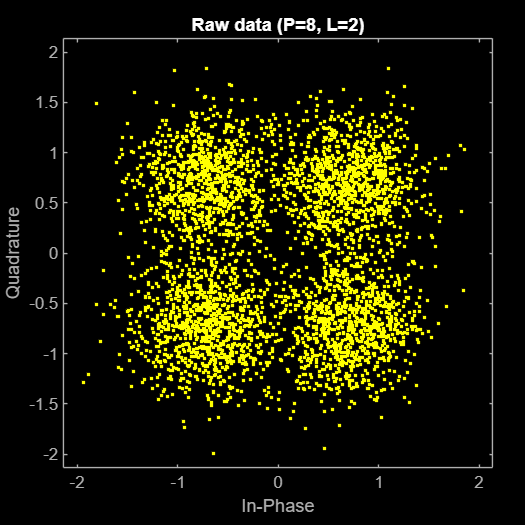

% Data model: x = h * s + w --> X = HS + W
P = 8; L = 2; delay = 1; sigma = 0.5;
x = gendata_conv(s,P,N,sigma);  % [NP x 1]
X = build_X(x,P,N,L);           % [2P x N-1]

[~, delay] = max(vecnorm(H));   % pick delay with strongest channel tap (to maximize SNR)

% Zero-forcing beamformer (white noise): w = inv(H'H)*H', force fit to zero difference (no noise assumption)
function H = build_H(P, L)
% Build hankel matrix H for the channel impulse response
    h = make_h(P);          % [P x 1]
    H = zeros(L*P, L);      % [LP x L]
    for k = 1:L
        H((k-1)*P+1 : k*P, k) = h;
    end
end
function H = build_H2(P, L)
    h = make_h(P);                    % [P×1]
    h_pad = [h; zeros((L-1)*P, 1)];  % pad to LP×1
    first_col = h_pad;                % [LP×1]
    first_row = zeros(1, L);          
    first_row(1) = h(1);
    H = toeplitz(first_col, first_row);  % [LP×L]
end
H = build_H(P,2);           % [LP x L]
w = pinv(H);                % [L x LP]
s_est_zf = w(delay,:)*X;    % [1 x N-1]

% Wiener receiver (white noise): w = min{||X - HS||^2} = inv(R_x)*r_xs
function s_delay = build_sd(s, N, L, delay)
% delay in 1:L
    idx_start = delay;                  % s index for n=1 is s_{delay-1} --> 1-based: s(delay)
    idx_end   = idx_start + (N-L);      % for n = N-L+1
    s_delay = s(idx_start : idx_end);   % [N-L+1 x 1]
end
s_delay = build_sd(s,N,L,delay);        % [N-1 x 1]
R_x = X * X' / (N-L);                   % sample auto-correlation matrix, [2P x N-1]x[N-1 x 2P] = [2P x 2P]
r_xs = X * conj(s_delay) / (N-1);       % sample cross-correlation matrix, [2P x N-1]x[N-1 x 1] = [2P x 1]

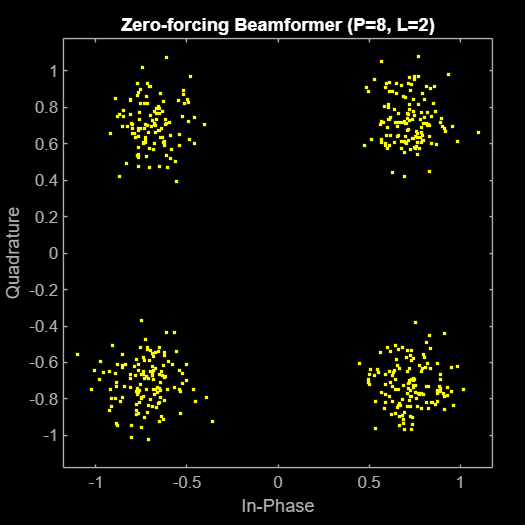


w = R_x \ r_xs;                         % [2P x 2P]x[2P x 1] = [2P x 1]
s_est_wiener = w'*X;                    % reconstructed s, [1 x 2P]x[2P x N-1] = [1 x N-1]


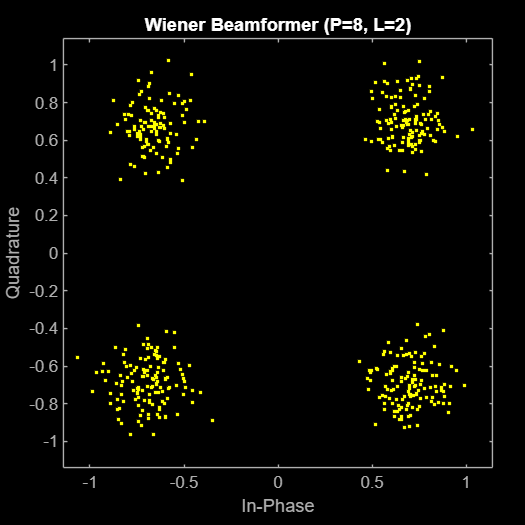

% Plot the two beamformer reconstructions in the complex plane versus raw data
figure;
scatterplot(x);

title(sprintf('Raw data (P=%d, L=%d)', P, L));

figure;
scatterplot(s_est_zf);
title(sprintf('Zero-forcing Beamformer (P=%d, L=%d)', P, L));

figure;
scatterplot(s_est_wiener);
title(sprintf('Wiener Beamformer (P=%d, L=%d)', P, L));